# Prac 6

clear all
addpath('~/Documents/EGB439/Robot_Functions')

## Access PiBot

pb = PiBot('172.19.232.178','172.19.232.11',6);

disp('1. Getting Robot Info')

1. Getting Robot Info


pose = pb.getLocalizerPose.pose;
x = pose.x;
y = 2-pose.y;
img = pb.getLocalizerImage();
disp(['....x = ',x])

....x =  


disp(['....y = ',y])

....y = 


## Compute Occupancy Grid

disp('2. Making Map')

2. Making Map


disp('.... * Thresholding for obstacles')

.... * Thresholding for obstacles


imgThreshhold = img > 20;
imgThreshhold(:,1:20) = 0;
imgThreshhold(:,end-20:end) = 0;
imgThreshhold(1:20,:) = 0;
imgThreshhold(end-20:end,:) = 0;

occupancyGrid = imresize(imgThreshhold, 1/5);

%Remove Robot
if x ~= 0 && y ~= 0
    disp('Removing Robot from occupancy grid')
    x1   = round(max(x*50 - 10,1));
    y1   = round(min(y*50 - 10,100));
    x2   = round(max(x*50 + 10,1));
    y2   = round(min(y*50 + 10,100));
    occupancyGrid(y1:y2,x1:x2) = 0;
else
    x = 90;
    y = 90;
end

## Find Path

disp('3. Analysing Map')

3. Analysing Map


start = ([1.6,1.6]/2) * 100;
goal = ([0.3,0.3]/2) * 100;

se = strel('disk',5);
expandedMap = imdilate(occupancyGrid,se);
expandedMap = flipud(expandedMap);

disp('.... * Computing Dist Transform')

.... * Computing Dist Transform


dtransform = myFunction('dxform', double(expandedMap), goal);


disp('.... * Computing Path')

.... * Computing Path


path = myFunction('path', double(dtransform), start, goal);
disp('........ * Path Found')

........ * Path Found


## Display Output

disp('4. Creating Graphical Representation')

4. Creating Graphical Representation


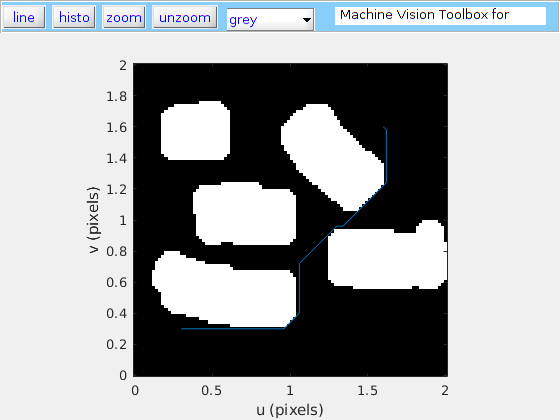



RGB = zeros(100,100,3);
RGB(:,:,1)   = occupancyGrid;
RGB(:,:,2)   = ones(100,100) - occupancyGrid;
pathDisp = 2*path/100;

figure
expandedMap = flipud(expandedMap);
idisp (expandedMap,'xydata',{[0,2] [2,0]},'ynormal')
hold on
plot(pathDisp(:,1),pathDisp(:,2))
hold off

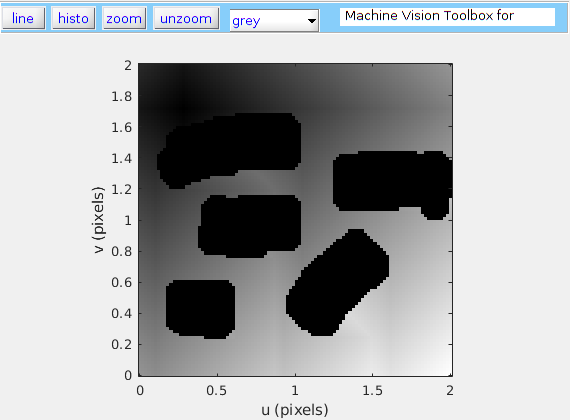


figure
idisp (dtransform,'xydata',{[0,2] [2,0]},'ynormal')
hold off

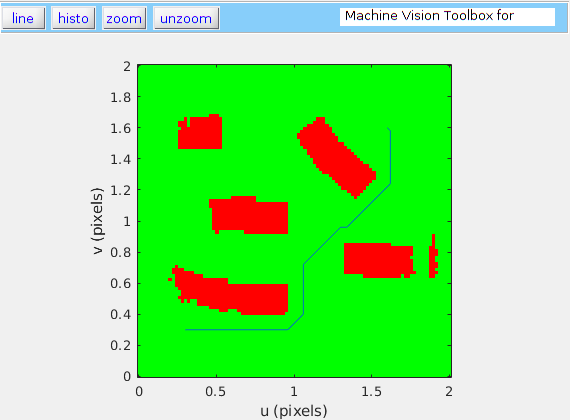


figure
idisp (RGB,'xydata',{[0,2] [2,0]},'ynormal')
hold on
plot(pathDisp(:,1),pathDisp(:,2))
hold off

## Pure Pursuit

d = 0.1;
dt = 0.25;

figure
rob = robotSim([[1.6,1.6], 0],dt);
first = 1;

for point = pathDisp.'    
    idisp (RGB,'xydata',{[0,2] [2,0]},'ynormal')    
    vel = control.purePursuit(point, rob.q, d, dt, first);  % compute the wheel speeds given the current configuration
    rob.update(vel);
    hold on
    rob.plot(0)
    plot(pathDisp(:,1),pathDisp(:,2),'r--')
    scatter(point(1),point(2),'rp')

    drawnow
    pause(0.01)
    
    
    
    first = 0;
    
end

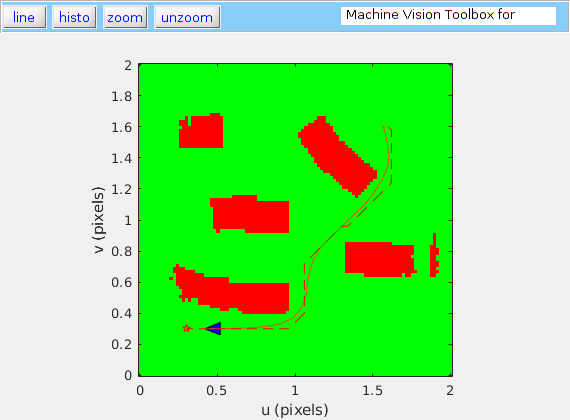


hold on
rob.plot()
plot(pathDisp(:,1),pathDisp(:,2),'r--')